# (5). NMR 1D peak fitting

### Introduction

In our previous examples we have studied the processing steps required to transform the FIDs into a comprehensible, high-quality frequency domain spectrum. This transformation, akin to an orchestra's symphony being deconstructed into its unique instrumental sounds, allows us to perceive the molecular intricacies of our samples. We have learnt how peak picking and integration of the peaks can be done in MATLAB. Such quantification of the signals can be used to understand the molecular makeup of the samples. The area under a peak is proportional to the number of resonating nuclei, enabling the determination of concentration and purity of substances.

The quantification stage of the spectra can be extended further by peak fitting, a process that involves modeling the NMR signals with mathematical functions to extract meaningful information from the spectra. Large samples with many nuclei may have multiple overlapping peaks, peak fitting is essential for resolving individual components, which might be challenging to distinguish through visual inspection alone. The linewidths and shapes of NMR peaks, extracted from fitting, can provide insights into molecular dynamics and interactions, giving clues about molecular motion, exchange processes, and phase changes. Rapid molecular motion tends to average out local magnetic inhomogeneities, resulting in narrower NMR peaks. Conversely, slower motions or restricted molecular dynamics can lead to broader peaks.

Fitting can also be used to accurately quantify the peak positions and comparison between different peaks can give insight into the coupling values, such as the spin-spin coupling. Chemists can also extract T1 and T2 relation times from fittings. The relaxation times (T1 and T2) influence the linewidths. Specifically, the transverse relaxation time (T2) is directly related to the linewidth. A shorter T2 relaxation time, often caused by interactions within the sample, results in broader linewidths.

### Lorentzian fitting

The line shapes in the NMR spectrum are determined by the process of Free Induction Decay. The time domain signal of the spectra follows an exponential decay so the peak fitting function often used is the Lorentzian. This follows because the Fourier transform of an exponential function in the time domain is a Lorentzian in the frequency domain.


$$L(f) = \frac{A \gamma^2}{(f - f_0)^2 + \gamma^2}$$
                  
$$FT\{L(f)\}(t) = A e^{-\gamma |t|} e^{2\pi i f_0 t}
$$


where *L*(*f*) is the Lorentzian function at frequency *f*, $A$ represents the amplitude, $f_0$ is the center frequency of the peak, and *γ* is the half-width at half-maximum (HWHM).

### Data Import and Plotting

We shall work with the spectrum of ethyl crotonate which has already been processed. It is in the time domain so we take the Fourier Transform of the FID. The spectrum has been phase corrected and we want to use the peaks in the real domain. This NMR data is kindly provided by Prof. Ilya Kuprov, University of Southampton.  

load('ethyl_crotonate_processed.mat','time_axis','ppm_axis','fid');
spectrum=real(fft(fid));

We normalize the spectra relative to the highest point of the intensity setting it to one.

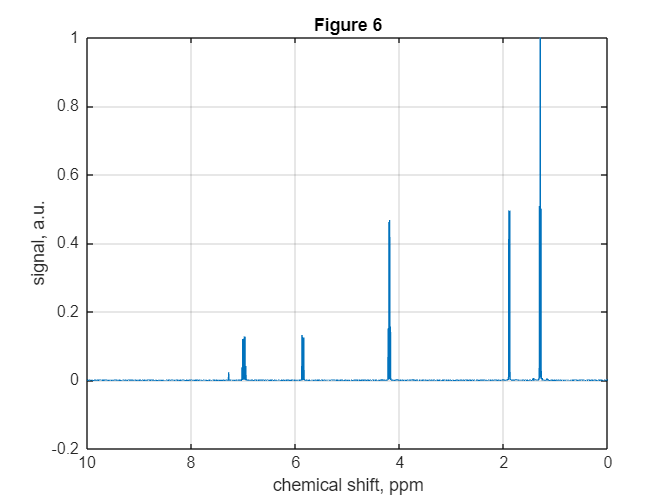

% Normalize the spectrum to have a maximum value of 1
spectrum = spectrum / max(abs(spectrum));

plot(ppm_axis,real(spectrum));set(gca,'XDir','reverse');
title('Figure 6'); grid; box on; ylabel('signal, a.u.');
xlabel('chemical shift, ppm'); 

The original spectrum contains many peaks, and it can take a significant time to fit all of them. Let us localize a region with several peaks. We can choose that to be in the region between 4.28-4.12 ppm.

We have isolated the Methlyne group (CH2 of the Ethyl Group) see a quartet due to splitting by the three (CH3) neighboring methyl group hydrogens.

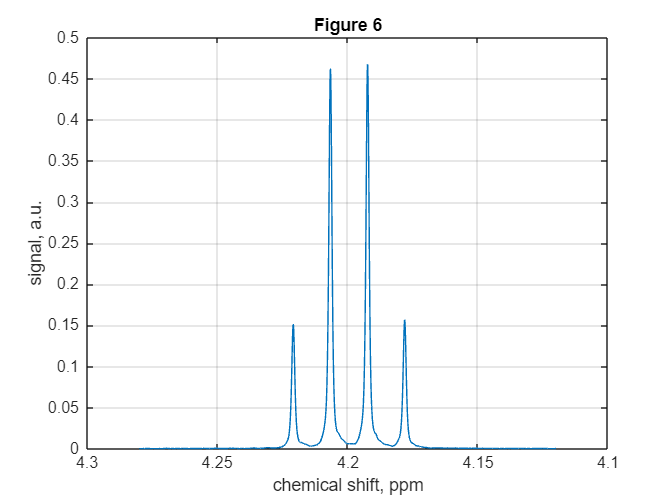

spectrum_bounds=findIndexFromPPM(ppm_axis',[4.28 4.12]);
spectrum=spectrum(spectrum_bounds(2):spectrum_bounds(1));
ppm_axis=ppm_axis(spectrum_bounds(2):spectrum_bounds(1));

plot(ppm_axis,real(spectrum));set(gca,'XDir','reverse');
title('Figure 6'); grid; box on; ylabel('signal, a.u.');
xlabel('chemical shift, ppm'); 

We define the Left and Right boundaries of our 4 peaks in a matrix, creating a matrix of 4x2. These values will initialize how many peaks need to be fitted and can be used to guess the initial parameters. 

peak_bounds = [4.23 4.213; 4.212 4.20; 4.1977 4.185; 4.183 4.17];

Find the corresponding index values of the frequency axis:

peak_index=findIndexFromPPM(ppm_axis',peak_bounds)

peak_index =         1443        1221
        1207        1050
        1020         853
         827         657


The fitting algorithm requires initial parameters to start the search. In our spectrum we have 4 peaks, hence a linear combination of 4 Lorentzians which need to be fitted. Each Lorentzian requires the initial guess of  *γ, *$A$ and $f_0$, hence we have a minimization of an unconstrained multivariable function with 12 parameters. This can be difficult, and the initial guess is very important, because if the initial parameters are far from the minimum the solution may not converge.

Luckily this can be done very easily in MATLAB from the boundary values and the spectrum itself. We run a FOR loop to go through each Lorentzian and estimate the initial parameters as:

- $A$ Amplitude - the maximum values of the spectrum within the peak boundary values

- *γ *HWHM *- *Half the difference between boundary values 

- $f_0$ Peak Centre - In the middle of the boundary values

% Initial guess for parameters
% A = amplitude, f0 = peak center frequency, gamma = half-width at half-maximum
initial_params = [];
for i = 1:size(peak_bounds,1)
    A = max(spectrum(peak_index(i,2):peak_index(i,1)));
    %f0 = peak_bounds(i,1);
    f0 = 0.5*(peak_bounds(i,1) + peak_bounds(i,2));
    gamma = abs(peak_bounds(i,2) - peak_bounds(i,1)) / 2;
    initial_params = [initial_params, [A; f0; gamma]];
end

The objective function must be defined. This is the function calculating how far away is the modelled spectrum from the true spectrum. In our case this would be the sum of the difference squared between the peak and the modelled linear combination of 4 Lorentzians.

% Objective function to minimize
objective = @(params) sum((spectrum - sum_lorentzians(ppm_axis, params, size(peak_bounds,1))).^2);

The optimisation parameters are defined here:

options = optimset('Display','iter','PlotFcns',@optimplotfval,'TolFun',0.001,'MaxIter',2e7,'MaxFunEvals',20000000);

We now call the nonlinear programming solver which will find the minimum of our defined objective function using the options and initial parameters specified.

The best fitted Lorentzian parameters will be returned.

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0          13          87.6051                      9.89e+03
     1          65          38.6355    1.02167e-06       6.96e+03  
     2          78           8.3219              1       5.25e+03  
     3         104          6.72327       0.314106       1.43e+03  
     4         130          6.47052       0.297395       1.09e+03  
     5         169          3.58195         1.9046       2.27e+03  
     6         208           3.4717      0.0335725        2.2e+03  
     7         221          2.57827              1       1.86e+03  
     8         234          1.82578              1            734  
     9         247         0.854902              1       1.17e+03  
    10         260         0.421676              1       1.42e+03  
    11         273         0.415088              1       1.23e+03  
    12         312          0.38861      0.031552

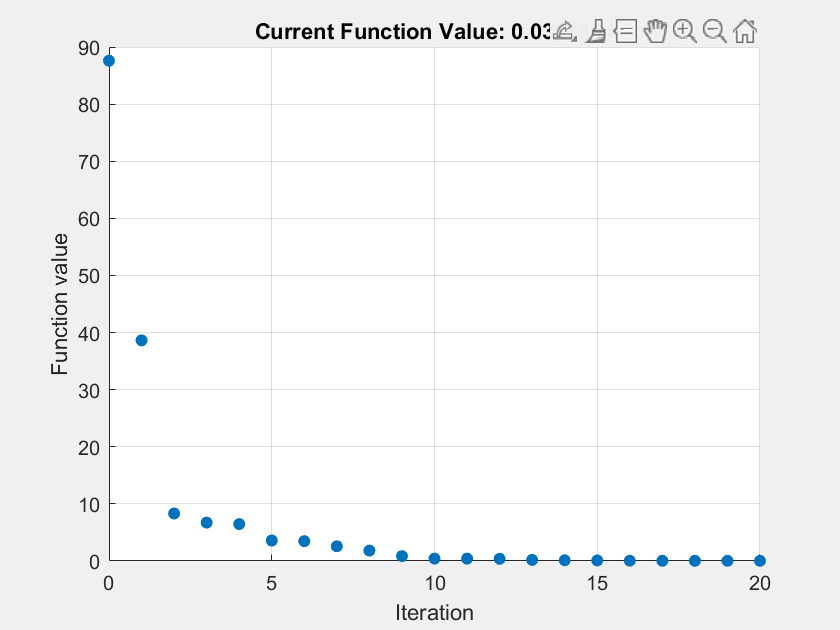

% Run the optimization
[fitted_params fval] = fminunc(objective, initial_params,options);

On the right you can see our convergence plot and the algorithm found a good solution in only 20 iterations. We can plot the overlay of our best fit model function and the original spectrum. As you can see the fitting of the linear combination of Lorentzians is very close to the spectrum. Now the best fit parameters can be accurately used to estimate the peak center, the width, and the amplitude.

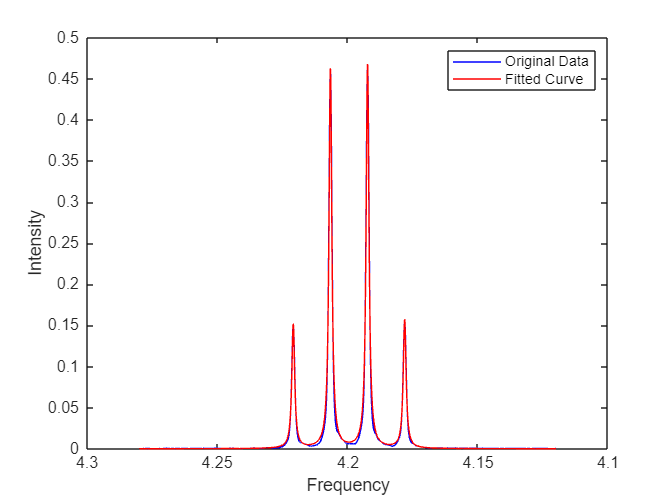


% Plot the results
fitted_curve = sum_lorentzians(ppm_axis, fitted_params, size(peak_bounds,1));
figure;
plot(ppm_axis, real(spectrum), 'b', ppm_axis, fitted_curve, 'r');set(gca,'XDir','reverse');
legend('Original Data', 'Fitted Curve');
xlabel('Frequency');
ylabel('Intensity');

### Summary

In this tutorial we have introduced 1D peak fitting using a linear combination of Lorentzian functions. Fitting is important, because it can be used to quantify the signal parameters which hold information on the molecular makeup of the sample. We selected the peaks we want to fit in the spectrum and used an optimization algorithm which finds the best parameters for our model.

### Utility functions

function sumL = sum_lorentzians(x, params, num_peaks)
    % Define the Lorentzian function
    lorentzian = @(A, f0, gamma, x) (A * gamma^2) ./ ((x - f0).^2 + gamma^2);

    sumL = zeros(size(x));
    % Calculate the linear combination of multiple Lorentzians
    for i = 1:num_peaks
        sumL = sumL + lorentzian(params(1,i), params(2,i), params(3,i), x);
    end
end

function index=findIndexFromPPM(axis,region)
    % Calculate the absolute differences between the array elements and the target
    differencesRg1  = abs(axis - region(:,1));
    differencesRg2 =  abs(axis - region(:,2));

    % Find the index of the minimum difference
    [~,index1] = min(differencesRg1 ,[],2);
    [~,index2] = min(differencesRg2 ,[],2);
    index=[index1 index2];
end

